clear
clc

N = 6;

%Pick expected data points for our measured FU values using sigmoidal
%equation with expected shape to response of cells to frequency
x_points = [0,1,1.2,1.4,1.6,1.8];
y_points = 1./(1+exp(-4.*x_points+3));

%%%%Least squares curve fit: 
%%%This is what they used in the Massey et al paper to do their calculations
%%Documentation available at: 
%https://www.mathworks.com/help/optim/ug/lsqcurvefit.html

%Function for LS
fun = @(a,x)1./(1+exp(-a(1)*x+a(2)));
x0 = [0,0.47];

a = lsqcurvefit(fun,x0,x_points,y_points);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


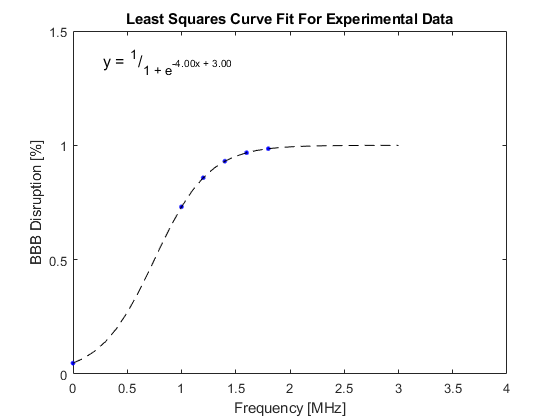


x_curve = [0:.1:3];
y_curve = 1./(1+exp(-a(1).*x_curve+a(2)));

%Plot points and curve fit
figure
plot(x_points,y_points, 'LineStyle', "none",'Marker','.', 'MarkerSize', 10,'Color', 'blue')
hold on
plot(x_curve,y_curve, 'lineStyle', '--', 'Color', 'black')
xlim([0 4])
ylim([0 1.5])
xlabel('Frequency [MHz]')
ylabel('BBB Disruption [%]')
title('Least Squares Curve Fit For Experimental Data')

% Add equation text as annotation
numerator = sprintf('1');
denominator = sprintf('1 + e^{-%.2fx + %.2f}', a(1), a(2));
ann_coord = [0.25, 0.8, 0.1, 0.1];
text = sprintf('y = ^{%s}/_{%s}',numerator,denominator);
annotation('textbox',ann_coord,'String',text,'FontSize', 12, 'HorizontalAlignment', 'center', 'EdgeColor', 'none');


data_out = [x_curve;y_curve];
%Save Data
save('data.mat','data_out')

